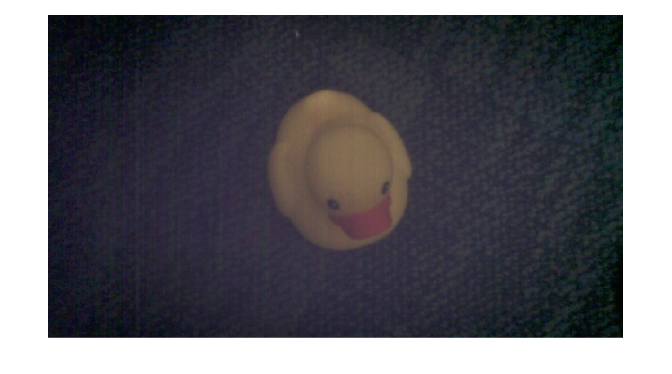

duck = imread("IMAGE016.jpg");
imshow(duck)

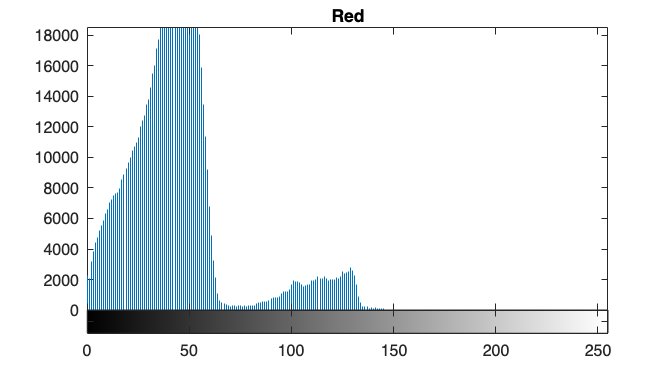


duck_red = duck(:, :, 1);
duck_green = duck(:, :, 2);
duck_blue = duck(:, :, 3);


imhist(duck(:, :, 1))
title("Red")

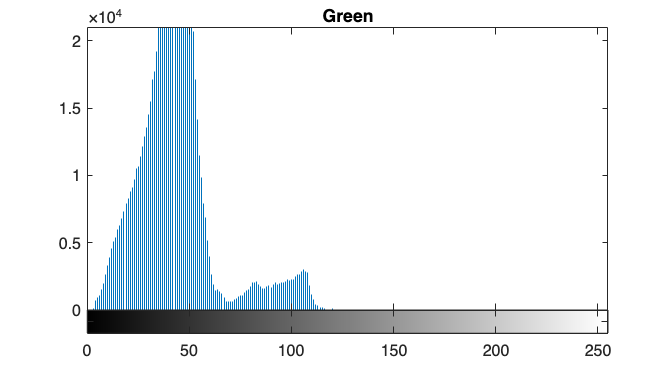


imhist(duck(:, :, 2))
title("Green")

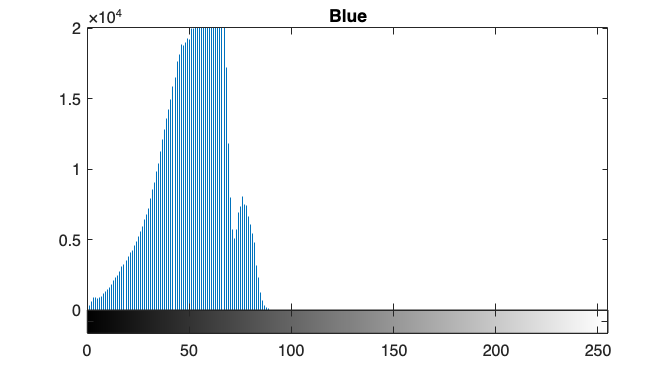


imhist(duck(:, :, 3))
title("Blue") 

duck_red(duck_red > 160) 


ans =

  0×1 empty uint8 column vector



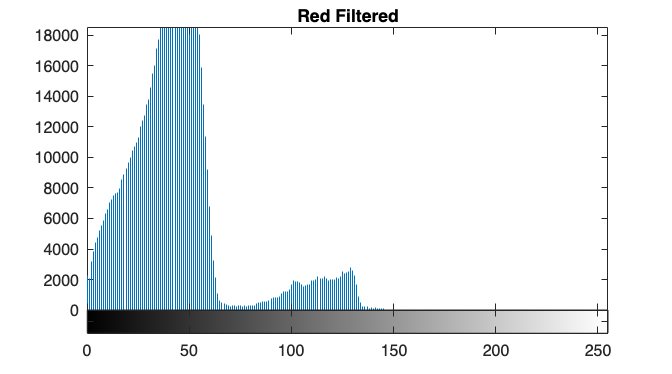

imhist(duck_red)
title("Red Filtered")


imhist(duck(:, :, 2))
title("Green")


imhist(duck(:, :, 3))
title("Blue")

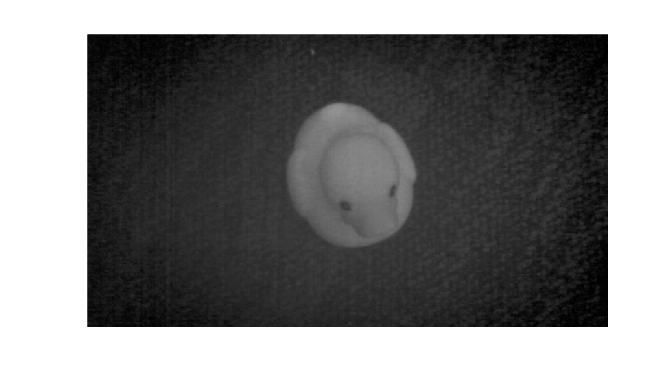


imshow(duck_red)

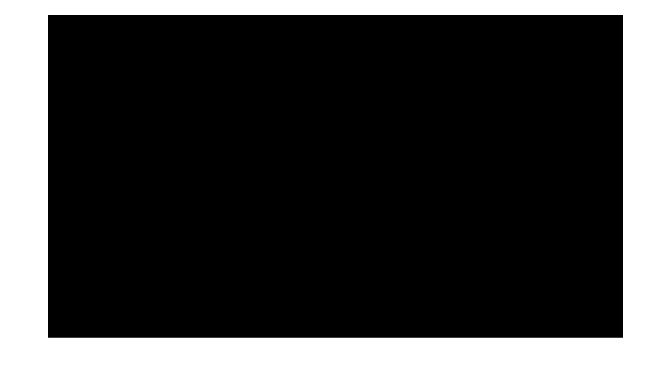

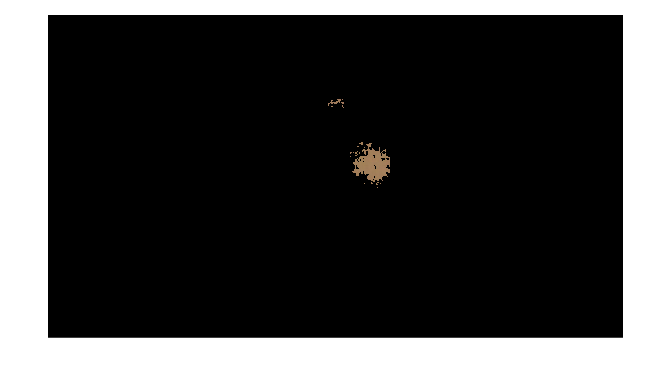

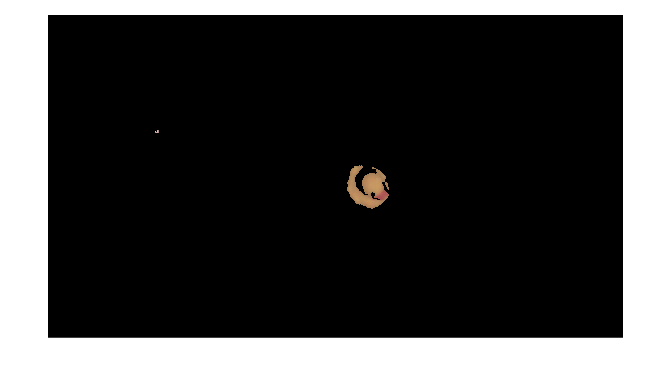

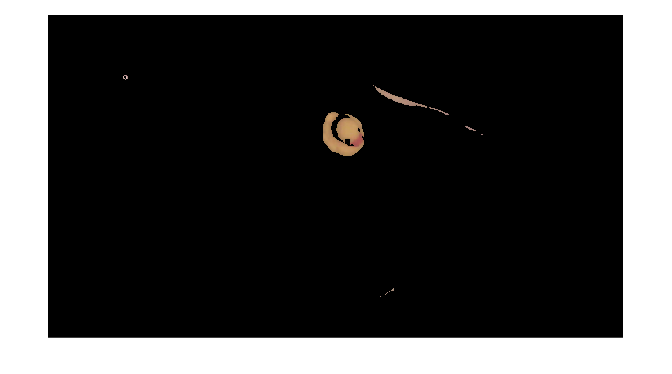

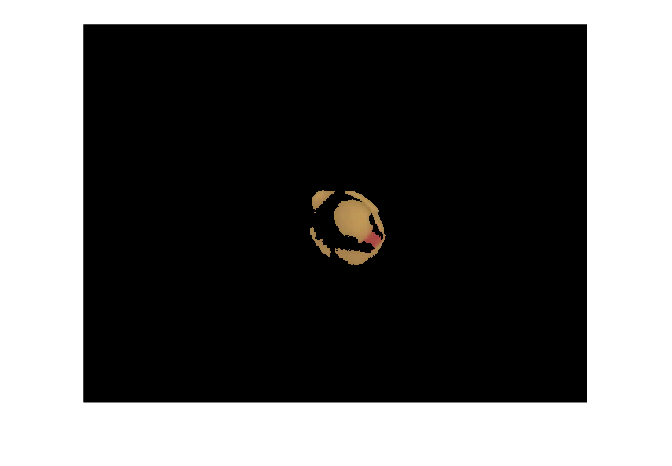

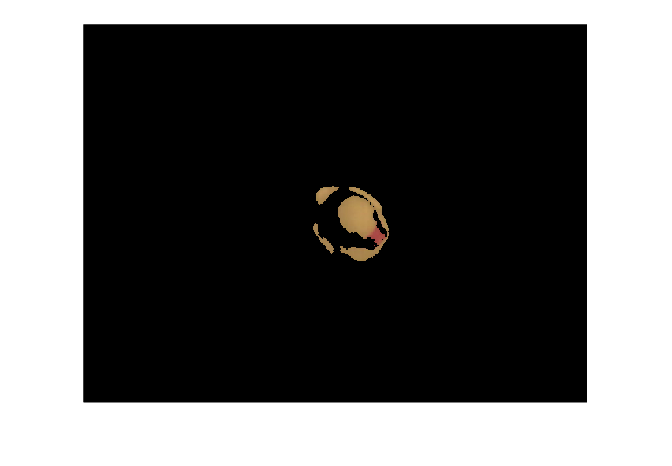

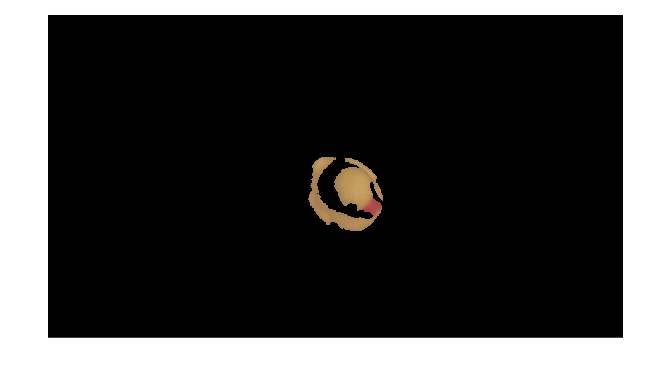

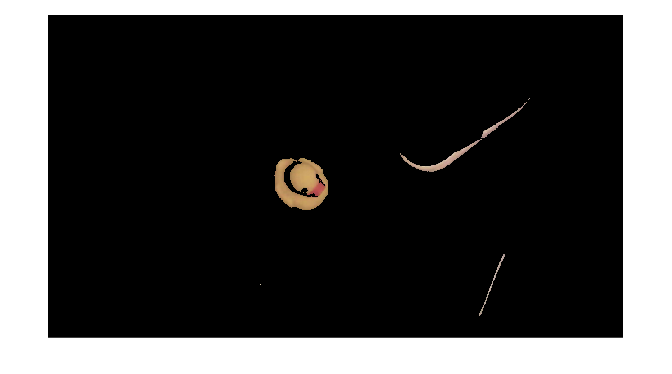

% images = ["IMAGE016.jpg", "IMAGE017.jpg", "IMAGE018.jpg", "IMAGE019.jpg", "IMAGE020.jpg", ...
%           "IMAGE021.jpg", "IMAGE022.jpg", "IMAGE023.jpg", "IMAGE024.jpg", "IMAGE025.jpg", ...
%           "IMAGE026.jpg", "IMAGE027.jpg", "IMAGE028.jpg", "IMAGE029.jpg", "IMAGE030.jpg", ...
%           "IMAGE031.jpg", "IMAGE032.jpg"];
% 
% lower_threshold = 160;
% 
% upper_threshold = 230;
% 
% for i = 1:length(images)
%     red_filtering(images(i), lower_threshold, upper_threshold)
% end



function red_filtering(image, lower_threshold, upper_threshold)
duck = imread(image);

duck_red = duck(:, :, 1);
duck_green = duck(:, :, 2);
duck_blue = duck(:, :, 3);


duck_red(duck_red < lower_threshold) = 0;
duck_red(duck_red > upper_threshold) = 0;

duck_green(duck_red < lower_threshold) = 0;
duck_green(duck_red > upper_threshold) = 0;

duck_blue(duck_red < lower_threshold) = 0;
duck_blue(duck_red > upper_threshold) = 0;

duck(:, :, 1) = duck_red;
duck(:, :, 2) = duck_green;
duck(:, :, 3) = duck_blue;

figure
imshow(duck);
% title("Duck - Red Filterd")
end



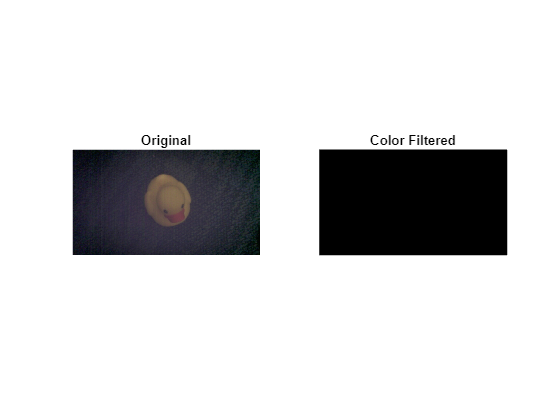

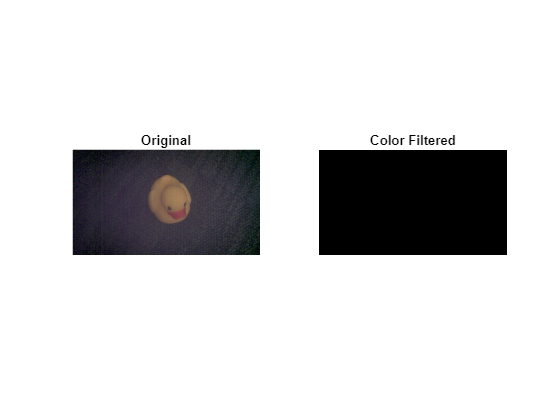

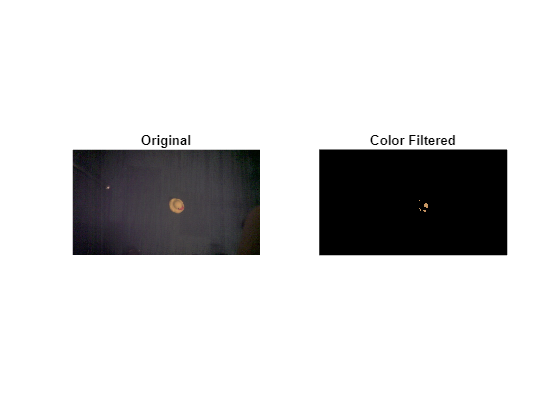

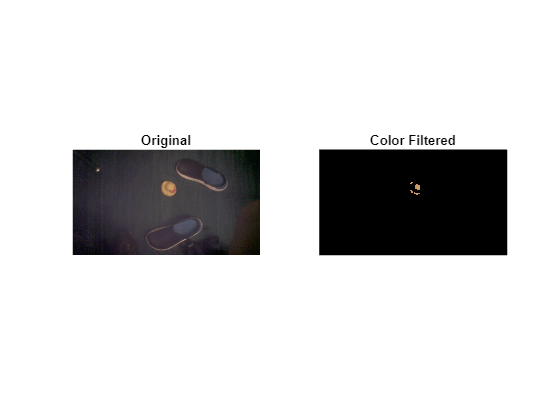

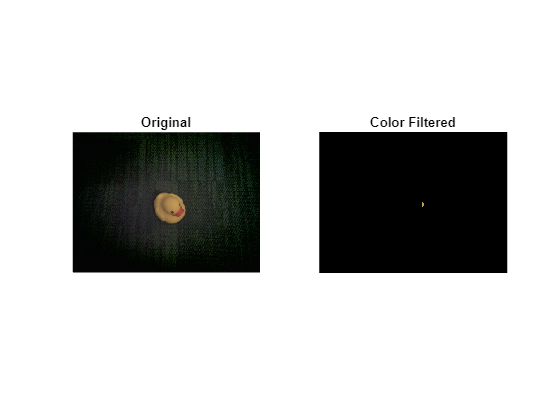

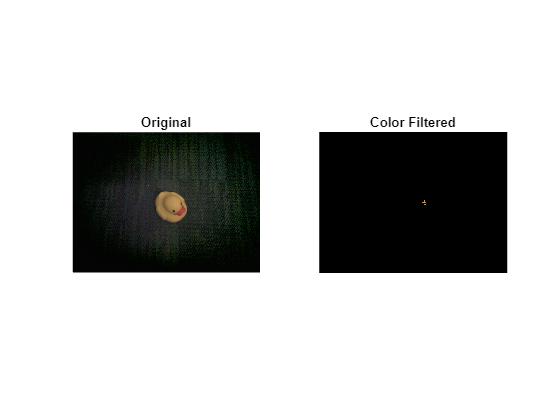

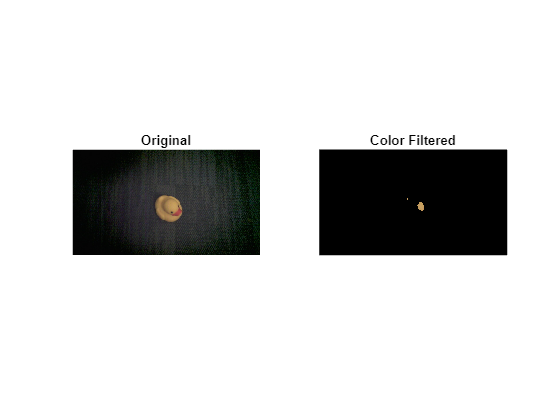

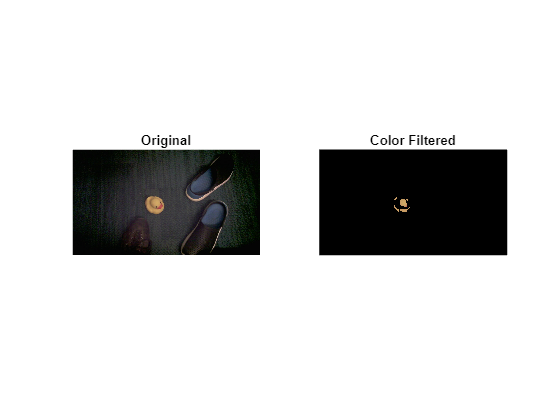

% images = ["IMAGE016.jpg", "IMAGE017.jpg", "IMAGE018.jpg", "IMAGE019.jpg", "IMAGE020.jpg"...
%           "IMAGE021.jpg", "IMAGE022.jpg", "IMAGE023.jpg", "IMAGE024.jpg", "IMAGE025.jpg"...
%           "IMAGE026.jpg", "IMAGE027.jpg", "IMAGE028.jpg", "IMAGE029.jpg", "IMAGE030.jpg"...
%           "IMAGE031.jpg", "IMAGE032.jpg", "IMAGE033.jpg", "IMAGE034.jpg", "IMAGE035.jpg"...
%           "IMAGE036.jpg", "IMAGE037.jpg", "IMAGE038.jpg", "IMAGE039.jpg", "IMAGE040.jpg"...
%           "IMAGE041.jpg", "IMAGE042.jpg", "IMAGE043.jpg", "IMAGE044.jpg", "IMAGE045.jpg"...
%           "IMAGE046.jpg", "IMAGE047.jpg", "IMAGE048.jpg", "IMAGE049.jpg", "IMAGE050.jpg"...
%           "IMAGE051.jpg"];
% 
% for i = 1:length(images)
%     color_filter(images(i))
% end

% 

% color_filter("IMAGE042.jpg")
% 
% function color_filter(image)
% 
% red_lower_threshold = 190;
% red_upper_threshold = 230;
% 
% green_lower_threshold = 90;
% green_upper_threshold = 200;
% 
% blue_lower_threshold = 50;
% blue_upper_threshold = 130;
% 
% duck = imread(image);
% duck_out = duck;
% 
% duck_red = duck(:, :, 1);
% duck_green = duck(:, :, 2);
% duck_blue = duck(:, :, 3);
% 
% for i = 1:size(duck, 1)
%     for j = 1:size(duck, 2)
%         if not ...
%             (duck_red(i, j) > red_lower_threshold && ...
%             duck_red(i, j) < red_upper_threshold && ...
%             duck_green(i, j) > green_lower_threshold && ...
%             duck_green(i, j) < green_upper_threshold && ...
%             duck_blue(i, j) > blue_lower_threshold && ...
%             duck_blue(i, j) < blue_upper_threshold)
% 
%             duck_red(i, j) = 0;
%             duck_green(i, j) = 0;
%             duck_blue(i, j) = 0;
%         end
%     end
% end
% 
% duck_out(:,:, 1) = duck_red;
% duck_out(:,:, 2) = duck_green;
% duck_out(:,:, 3) = duck_blue;
% 
% figure
% subplot(1, 2, 1)
% imshow(duck)
% title("Original")
% subplot(1, 2, 2)
% imshow(duck_out)
% title("Color Filtered")
% end

images = ["IMAGE016.jpg", "IMAGE017.jpg", "IMAGE018.jpg", "IMAGE019.jpg", "IMAGE020.jpg", ...
          "IMAGE021.jpg", "IMAGE022.jpg", "IMAGE023.jpg", "IMAGE024.jpg", "IMAGE025.jpg", ...
          "IMAGE026.jpg", "IMAGE027.jpg", "IMAGE028.jpg", "IMAGE029.jpg", "IMAGE030.jpg", ...
          "IMAGE031.jpg", "IMAGE032.jpg", "IMAGE033.jpg", "IMAGE034.jpg", "IMAGE035.jpg", ...
          "IMAGE036.jpg", "IMAGE037.jpg", "IMAGE038.jpg", "IMAGE039.jpg", "IMAGE040.jpg", ...
          "IMAGE041.jpg", "IMAGE042.jpg", "IMAGE043.jpg", "IMAGE044.jpg", "IMAGE045.jpg", ...
          "IMAGE046.jpg", "IMAGE047.jpg", "IMAGE048.jpg", "IMAGE049.jpg", "IMAGE050.jpg", ...
          "IMAGE051.jpg"];

for i = 1:length(images)
    color_filter(images(i), i)
end

function color_filter(image, idx)

red_lower_threshold = 190;
red_upper_threshold = 230;

green_lower_threshold = 90;
green_upper_threshold = 200;

blue_lower_threshold = 50;
blue_upper_threshold = 130;

duck = imread(image);
duck_out = duck;

duck_red = duck(:, :, 1);
duck_green = duck(:, :, 2);
duck_blue = duck(:, :, 3);

for i = 1:size(duck, 1)
    for j = 1:size(duck, 2)
        if not ...
            (duck_red(i, j) > red_lower_threshold && ...
            duck_red(i, j) < red_upper_threshold && ...
            duck_green(i, j) > green_lower_threshold && ...
            duck_green(i, j) < green_upper_threshold && ...
            duck_blue(i, j) > blue_lower_threshold && ...
            duck_blue(i, j) < blue_upper_threshold)

            duck_red(i, j) = 0;
            duck_green(i, j) = 0;
            duck_blue(i, j) = 0;
        end
    end
end

duck_out(:,:, 1) = duck_red;
duck_out(:,:, 2) = duck_green;
duck_out(:,:, 3) = duck_blue;

% Create and save the output figure
figure('Visible', 'off');
subplot(1, 2, 1)
imshow(duck)
title("Original")
subplot(1, 2, 2)
imshow(duck_out)
title("Color Filtered")
saveas(gcf, sprintf('filtered_duck_%03d.png', idx)); % Save the figure
close(gcf); % Close the figure to prevent memory issues
end
